# pre-requistite knowledge

## the model of the pendulum

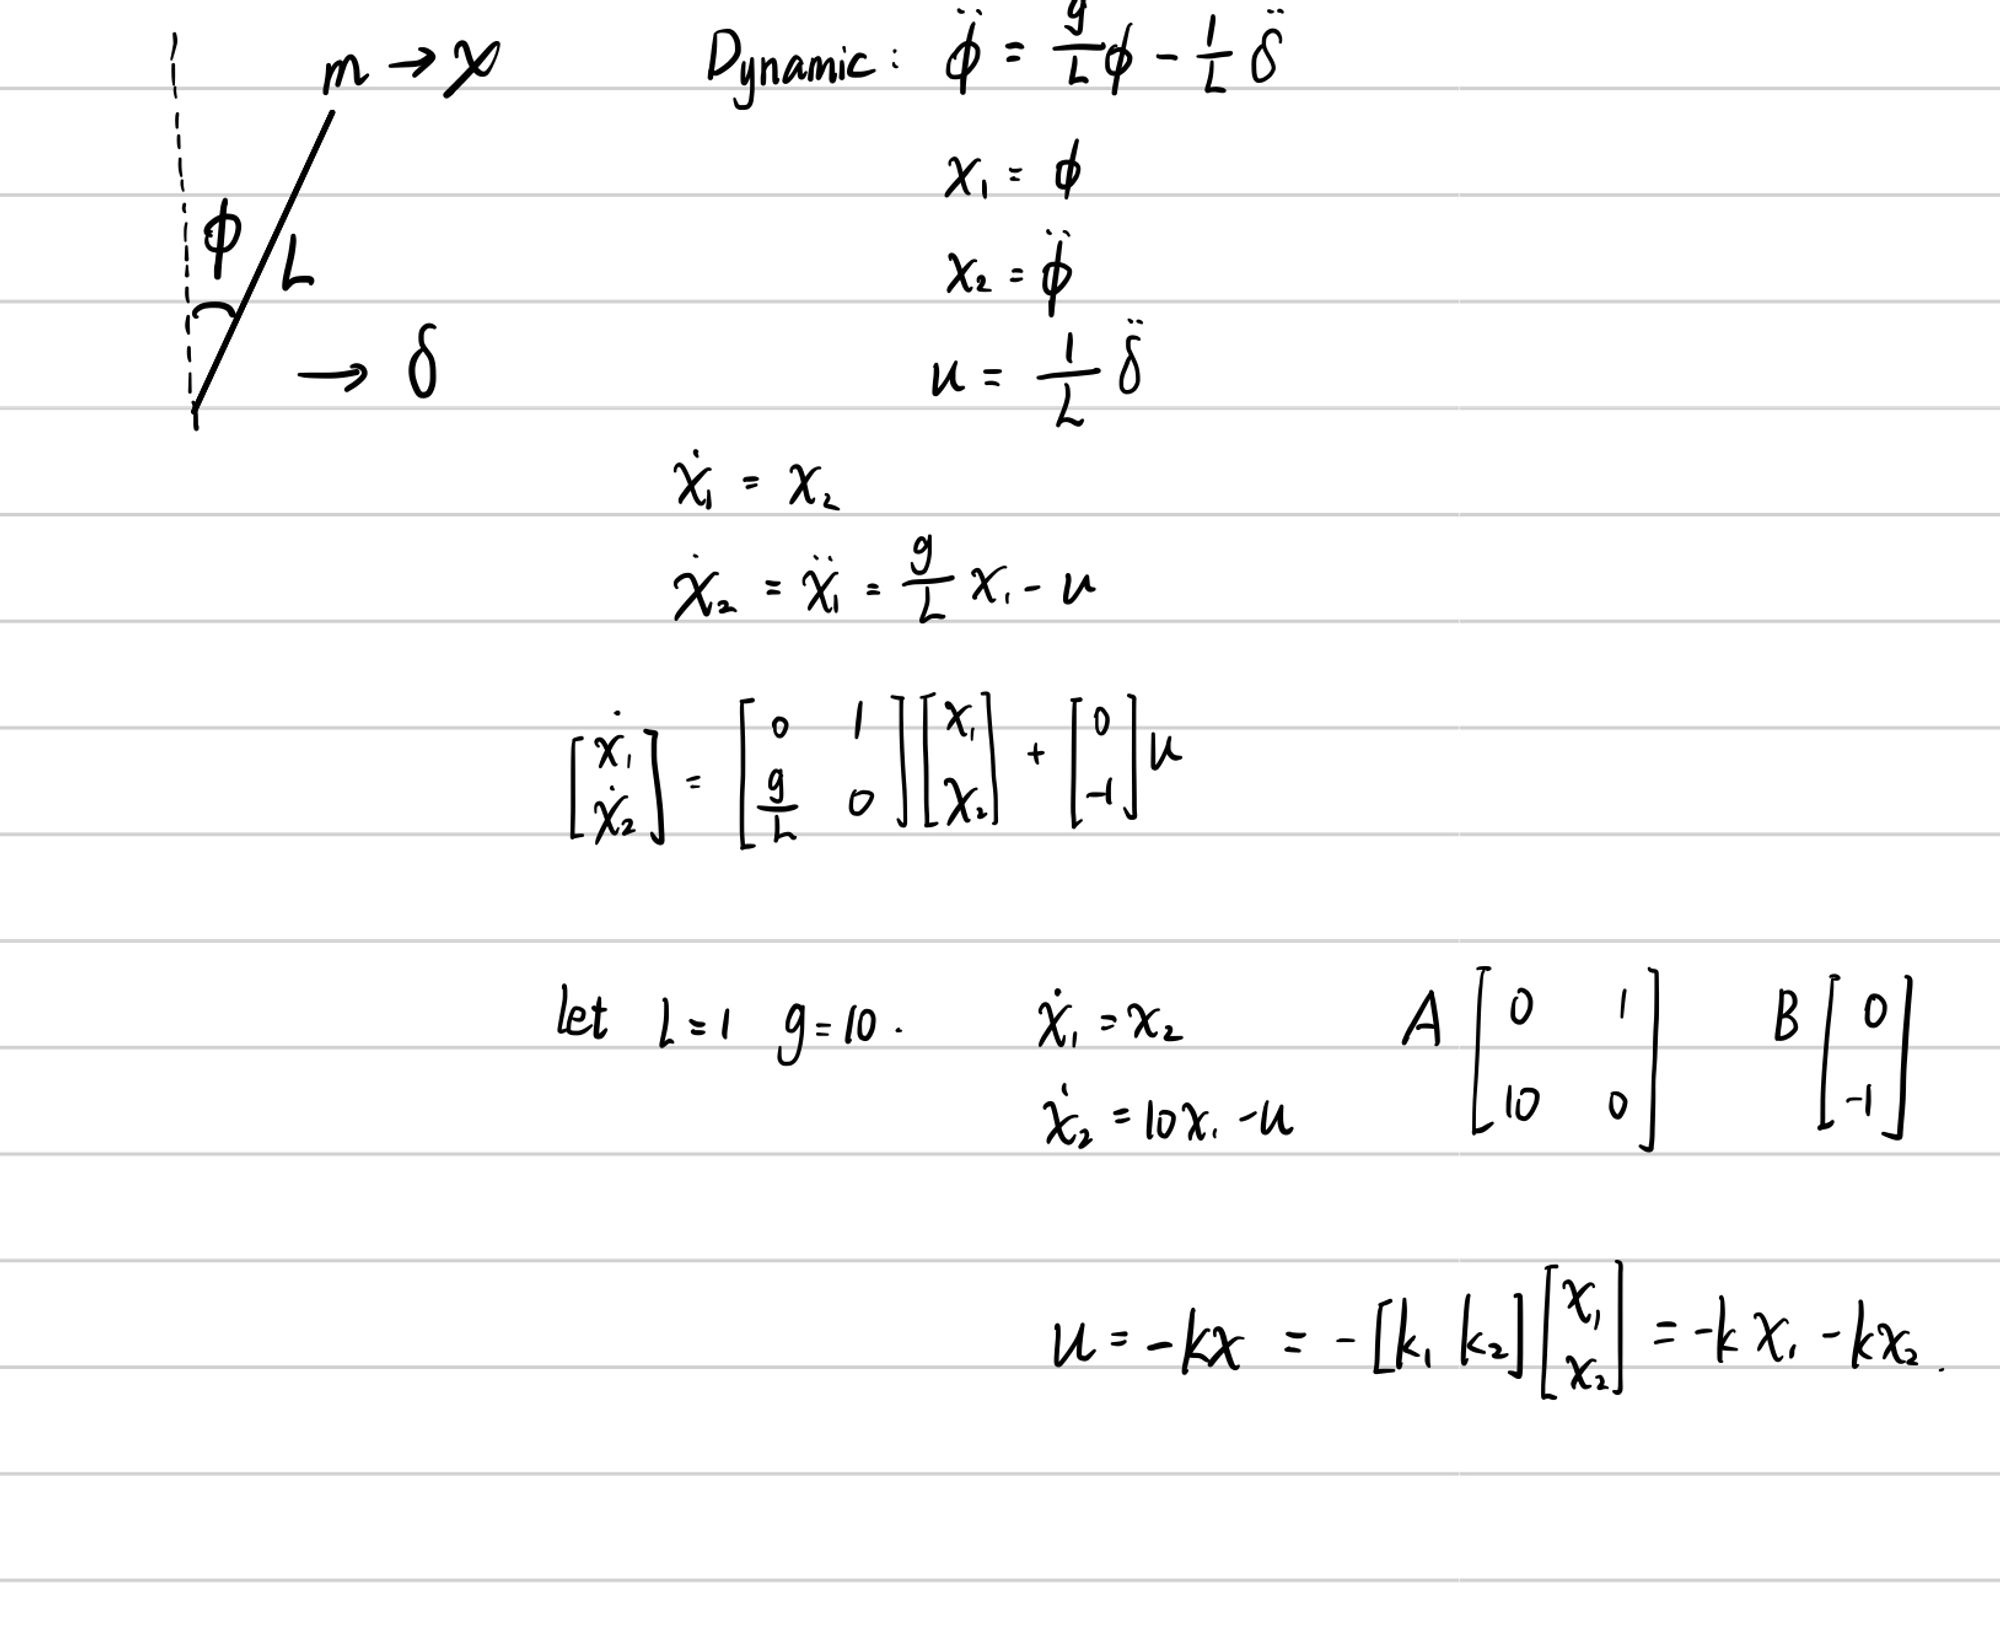

## explanation of the param

L: Linear

Q: Quadratic

R: Regulater

## Cost function of LQR


$$J=\int_0^{\infty } \left(X^T \textrm{QX}+U^T \textrm{RU}\right)\textrm{dt}$$


And we need to find the minist cost of the system.

which is "$\min \;J$".

# simulation in simulink

% setpoint 
SP = 0;

% the state of the system
A = [0 1;10 0];
B = [0;1];
C = eye(2);
D = [0;0];

% if the feedback param is 0
K = [0 0];
threshold = 1;

% run the simulation model
open_system('LQR_DW.slx')

## implement the LQR control algorithm

then we optimise the system with LQR.

% Q: Quadratic
Q = [100 0;0 1];
% R: Regulater
R = 0.01

R = 0.0100


K = lqr(A,B,Q,R)

K =   110.4988   17.9164
